% Load the dataset
data = readtable('IBM_2006-01-01_to_2018-01-01.csv');
data

data = 3020×7 table
       Date       Open     High      Low     Close      Volume       Name  
    __________    _____    _____    _____    _____    __________    _______

    2006-01-03    82.45    82.55    80.81    82.06    1.1715e+07    {'IBM'}
    2006-01-04     82.2     82.5    81.33    81.95    9.8406e+06    {'IBM'}
    2006-01-05     81.4     82.9       81     82.5    7.2135e+06    {'IBM'}
    2006-01-06    83.95    85.03    83.41    84.95    8.1974e+06    {'IBM'}
    2006-01-09     84.1    84.25    83.38    83.73    6.8582e+06    {'IBM'}
    2006-01-10    83.15    84.12    83.12    84.07     5.701e+06    {'IBM'}
    2006-01-11    84.37    84.81     83.4    84.17    5.7765e+06    {'IBM'}
    2006-01-12    83.82    83.96     83.4    83.57    4.9

## 1. Check Data Structure and Plot it

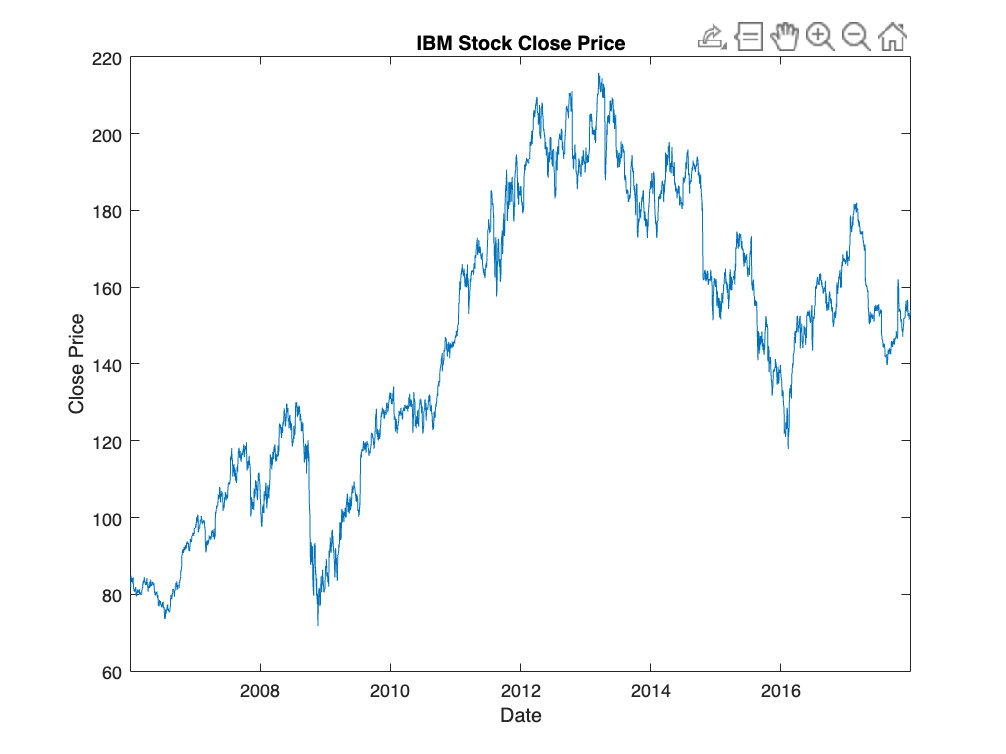


plot(data.Date, data.Close);
xlabel('Date');
ylabel('Close Price');
title('IBM Stock Close Price');

## 2. Check for Missing Values


%Removing the last column since it is a constant with value "MSFT"
data(:,end) = [];
summary(data);

Variables:

    Date: 3020×1 datetime

        Values:

            Min       2006-01-03
            Median    2011-12-29
            Max       2017-12-29

    Open: 3020×1 double

        Values:

            Min             72.74   
            Median          149.61  
            Max             215.38  
            NumMissing      1       

    High: 3020×1 double

        Values:

            Min         73.94 
            Median     150.33 
            Max         215.9 

    Low: 3020×1 double

        Values:

            Min             69.5    
            Median          148.47  
            Max             214.3   
            NumMissing      1       

    Close: 3020×1 double

        Values:

            Min         71.74 
            Median     149.31 
            Max         215.8 

    Volume: 3020×1 double

        Values:

            Min       2.5426e+05
           

disp('Number of Missing Values for Each Column:');

Number of Missing Values for Each Column:


disp(sum(ismissing(data)));

     0     1     0     1     0     0     0




%% Find range of data according to data
dateRange = [min(data.Date) max(data.Date)]

dateRange = 1×2 datetime array
   2006-01-03   2017-12-29


## 3. Plot for Open, High, Low, Close, Volume

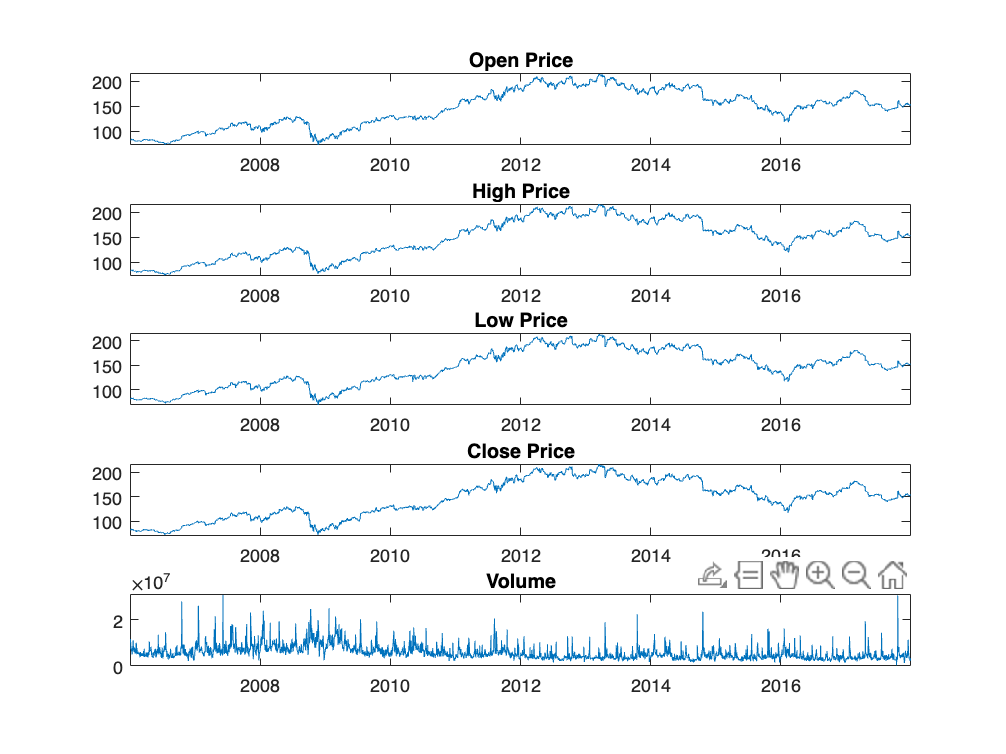

dataColumn = ["Open","High","Low","Close","Volume"];

figure;
subplot(5,1,1);
plot(data.Date, data.Open);
title('Open Price');

subplot(5,1,2);
plot(data.Date, data.High);
title('High Price');

subplot(5,1,3);
plot(data.Date, data.Low);
title('Low Price');

subplot(5,1,4);
plot(data.Date, data.Close);
title('Close Price');

subplot(5,1,5);
plot(data.Date, data.Volume);
title('Volume');

## 4. Extract and Plot Trend Analysis (using a moving average for simplicity)

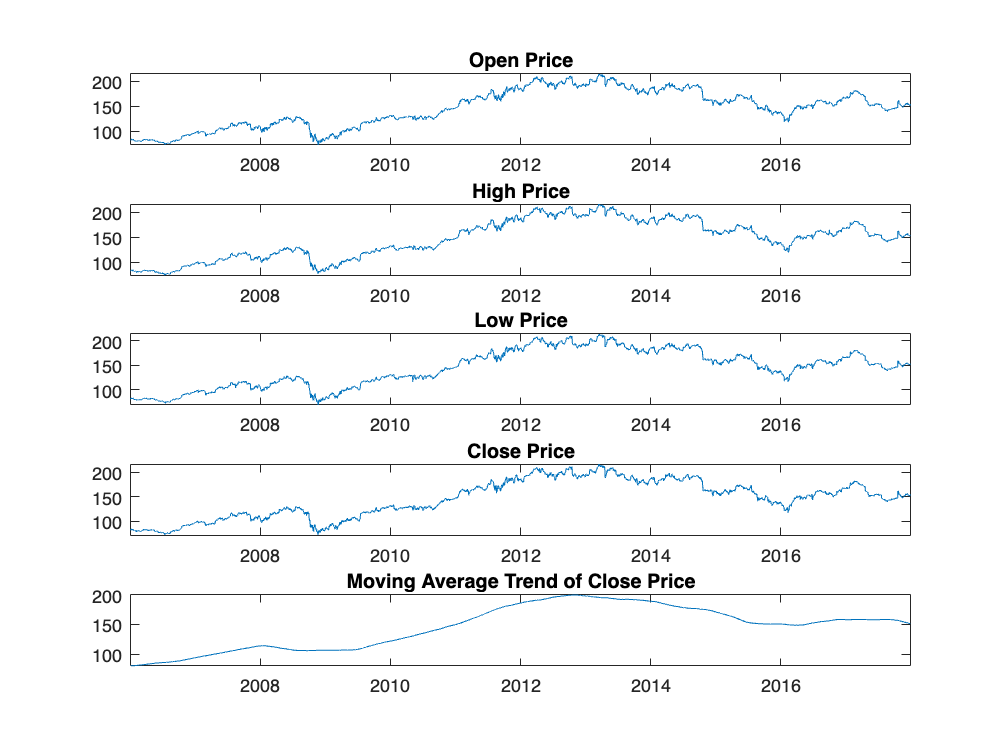


windowSize = 365; % Adjust as needed
movAvg = movmean(data.Close, windowSize);
plot(data.Date, movAvg);
title('Moving Average Trend of Close Price');

## 5. Make Distribution Plots

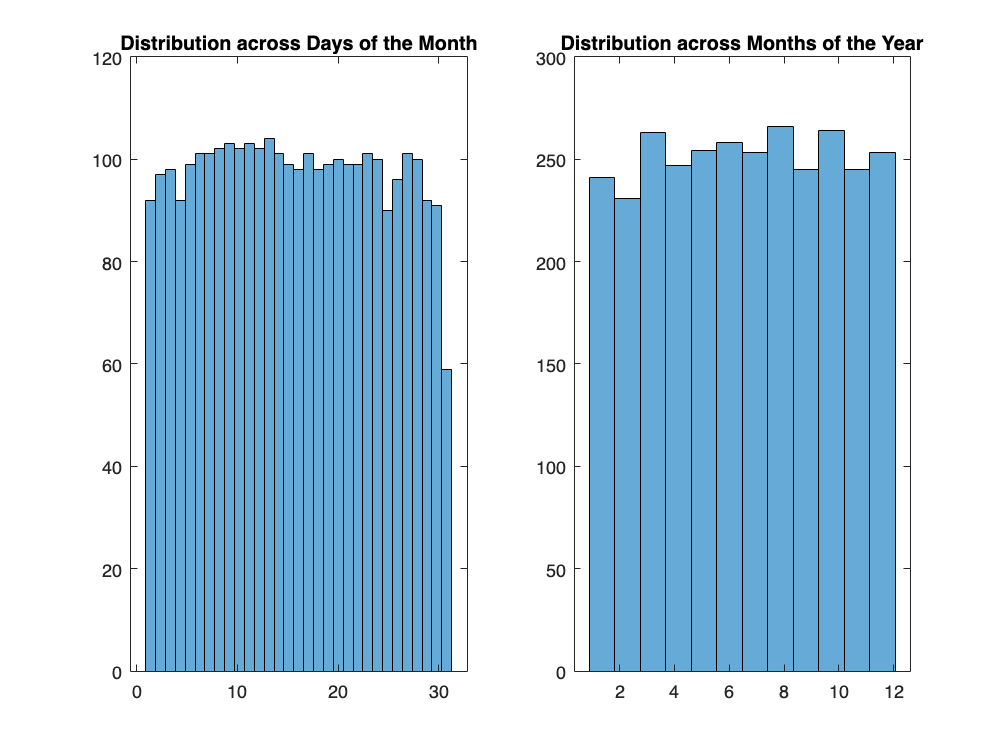


data.Day = day(data.Date);
data.Month = month(data.Date);

figure;
subplot(1,2,1);
histogram(data.Day, 31);
title('Distribution across Days of the Month');

subplot(1,2,2);
histogram(data.Month, 12);
title('Distribution across Months of the Year');

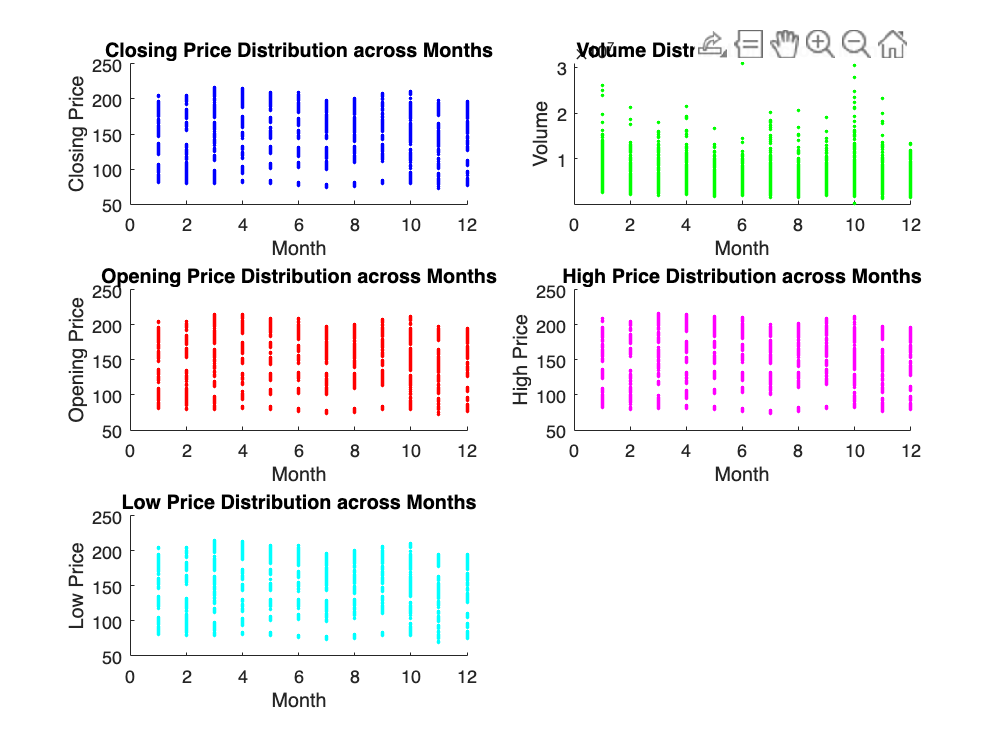


figure
% Closing Price Distribution
subplot(3, 2, 1);
scatter(month(data.Date), data.Close, 'b.');
title("Closing Price Distribution across Months");
xlabel("Month");
ylabel("Closing Price");

% Volume Distribution
subplot(3, 2, 2);
scatter(month(data.Date), data.Volume, 'g.');
title("Volume Distribution across Months");
xlabel("Month");
ylabel("Volume");

% Opening Price Distribution
subplot(3, 2, 3);
scatter(month(data.Date), data.Open, 'r.');
title("Opening Price Distribution across Months");
xlabel("Month");
ylabel("Opening Price");

% High Price Distribution
subplot(3, 2, 4);
scatter(month(data.Date), data.High, 'm.');
title("High Price Distribution across Months");
xlabel("Month");
ylabel("High Price");

% Low Price Distribution
subplot(3, 2, 5);
scatter(month(data.Date), data.Low, 'c.');
title("Low Price Distribution across Months");
xlabel("Month");
ylabel("Low Price");
hold off

## 6. Decomposition of Variables

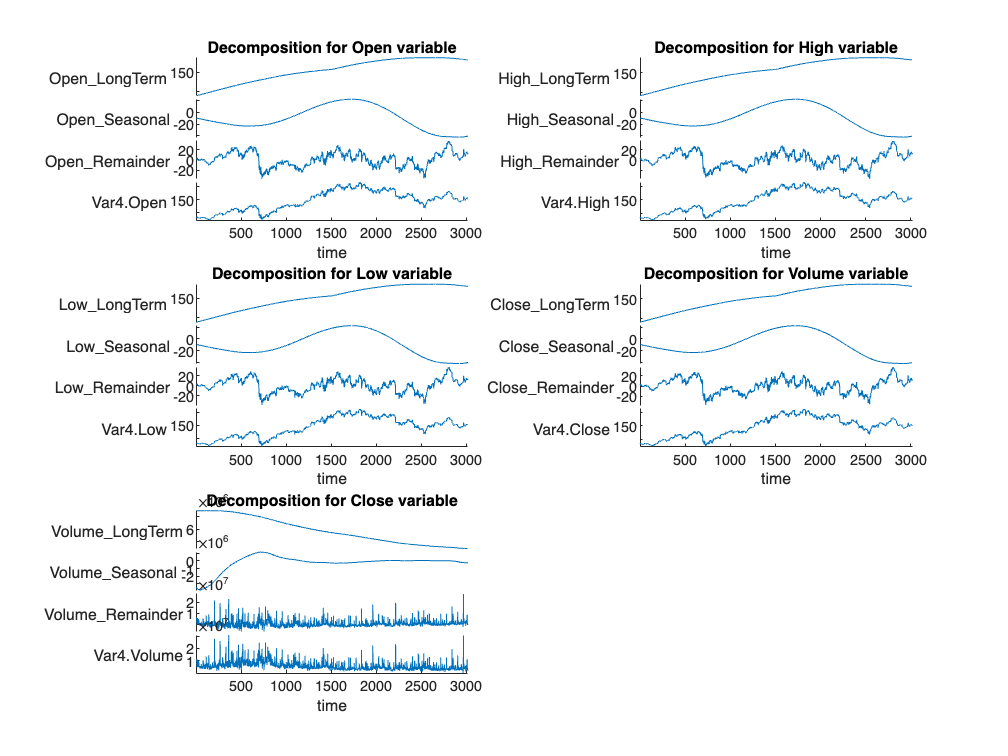


Columns = ["Open","High","Low","Volume","Close"];
figure
for i=2:6
    D = trenddecomp(data(:,i));
    D = addvars(D,data(:,i));
    subplot(3,2,i-1)
    stackedplot(D)
    xlabel("time")
    title("Decomposition for "+ Columns(i-1)+" variable") 
end